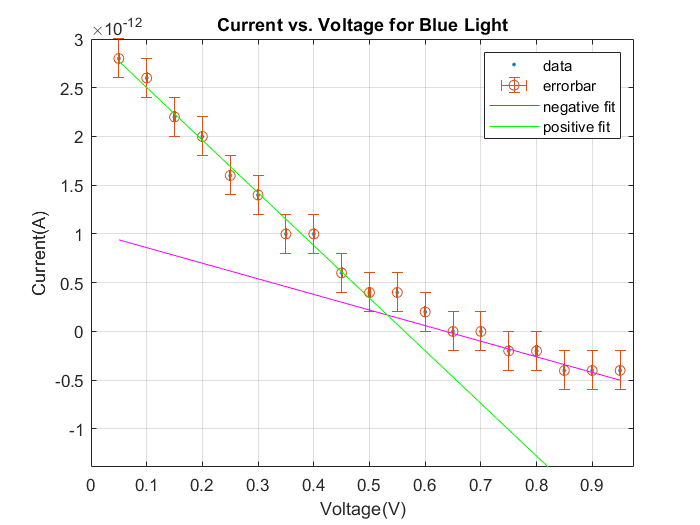

plot(BLUEvoltage,BLUEcurrent,'.')
hold on
%%CREATING ERROBARS
xneg=0.001.*[1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1];
xpos=xneg;
yneg=(0.2e-12).*[1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1];
ypos=yneg;
errorbar(BLUEvoltage,BLUEcurrent,yneg,ypos,xneg,xpos,'o')



%Negative side fit data
%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
%       p1 =    -1.600e-12  \mp 1.217e-12
%       p2 =    1.020e-12  \mp 1.006e-12

%Goodness of fit:
 % SSE: 8e-27
 % R-square: 0.8
 % Adjusted R-square: 0.7
 % RMSE: 6.325e-14
p1 =    -1.6e-12 ;
 p2 =    1.02e-12 ;
f=p1*BLUEvoltage+p2;


%Positive side fit data
%Linear model Poly1:
%     f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p3 =    -5.400e-12  \mp 0.286e-12
 %      p4 =   3.0420e-12  \mp 0.094e-12

%Goodness of fit:
 % SSE: 6.156e-26
 % R-square: 0.9861
  %Adjusted R-square: 0.9841
  %RMSE: 9.377e-14
  p3 =-5.4e-12;
   p4 = 3.042e-12;
   g=p3*BLUEvoltage+p4;
   
  
plot(BLUEvoltage,f,'m')
plot(BLUEvoltage,g,'g')

grid on

xlim([0.000 0.975])
ylim([-0.00000000000139 0.00000000000300])
legend({'data','errorbar','negative fit','positive fit'})
title('Current vs. Voltage for Blue Light')
xlabel('Voltage(V)')
ylabel('Current(A)')